# Reconstructing a Discrete Distribution Function

## Overview

Chapter 8 mentions recoving a discrete form of the orientation distribution function $\psi(\mathbf{p})$, starting from a second-order orientation tensor $\mathbf{A}$.  The reconstructed $\psi$ is represented by a discrete set of orientation vectors $\mathbf{p}^i$ and corresponding weights $f_i$.  

The reconstruction process shown here is based on the Jeffery distribution, which is fully determined by $\mathbf{A}$; however, any other distribution function could be used as well.  

Recall that the Jeffery distribution is given by


$$\psi(\mathbf{p}) = \frac{1}{4 \pi \left( \mathbf{p} \cdot \mathbf{B}^{-1} \cdot \mathbf{p} \right)^{-3/2}}$$


where $\mathbf{B}^{-1}$ is the Piola tensor, related to the deformation gradient tensor $\mathbf{F}$ by


$$\mathbf{B}^{-1} = \mathbf{F}^{-T} \cdot \mathbf{F}^{-1}$$


In a reconstruction process, the function `A2F` gives the $\mathbf{F}$ tensor corresponding to the known $\mathbf{A}$ tensor. 

One must also select the $\mathbf{p}^i$ vectors that will be used in the reconstruction.  These are usually distributed fairly uniformly on the unit sphere, and the area $a_i$ associated with each $\mathbf{p}^i$ must be determined.  Since $\psi(\mathbf{p}^i) = \psi(-\mathbf{p}^i)$, the $\mathbf{p}^i$ vectors and their areas only need to span a hemisphere of the orientation space.  

The initial weights $\hat{f}_i$ are then calculated as


$$\hat{f}_i = 2 a_i \: \psi(\mathbf{p}^i)$$


The factor of 2 appears because each point $\mathbf{p}^i$ represents its area $a_i$ and a matching area at $-\mathbf{p}^i$.

These weights will only satisfy the normalization condition approximately, so it is customary find normalized weights, $f_i = \hat{f}_i / \sum_j \hat{f}_j$, so that


$$\sum_i f_i = 1$$
 

Now the orientation average of any $\mathbf{p}$-dependent function $g(\mathbf{p})$can be computed as


$$\langle g \rangle = \sum_i f_i \; g(\mathbf{p}^i)$$


It is possible to also adjust the weights so that the weighted $\mathbf{p}^i$ values exactly reproduces the second-order orientation tensor,


$$\sum_i \mathbf{p}^i \mathbf{p}^i f_i = \mathbf{A}$$


or even the fourth-order orientation tensor, if that is known:


$$\sum_i \mathbf{p}^i \mathbf{p}^i  \mathbf{p}^i \mathbf{p}^i  f_i = \mathbf{A}^{(4)}$$


These adjustments compensate for the fact that the distribution function is not exactly equal to $\psi(\mathbf{p}^i)$ over each area $a_i$.  However, if the fibers are highly aligned (at least one eigenvalue of $\mathbf{A}$ is either close to unity or close to zero) then this adjustment process may give some  $f_i < 0$.  Negative weights are non-physical, and are difficult to deal with.  There is no robust process for this, so the tools here simply provide a warning when any $f_i < 0$.  This issue only arises when adjusting the weights to match an orientation tensor; the Jeffery distribution never has $\psi < 0$, so the initial weights will always be non-negative.    

## Choosing the Orientation Vectors

One way to choose the orientation vectors is to start with a coarse triangular mesh covering a hemisphere; refine the mesh as desired to increase the number of points; then use the centroid of each triangle as a $\mathbf{p}^i$ vector and the area of the triangle as the corresponding area $a_i$.  

In this toolkit, the `spheremesh` function creates and refines suitable meshes, and `sphTriArea` computes the area of spherical triangles in such a mesh.  The functions `plot3mesh`, `plot3nodes`, `fill3mesh` and `fill3elt` can be used to display the mesh, nodes, and color contours of nodal or element quantities.  

Here is an example.  The parent shape is 10 faces from an icosahedron (a solid with twenty congruent triangular faces).  Choosing this icosahedral "cap" eliminates half of the faces, avoiding any duplication of the $\mathbf{p}^i$ vectors.  (To see the full icoashedral mesh, change 'cap' to 'ico' in the call to `spheremesh` and re-run this section.)

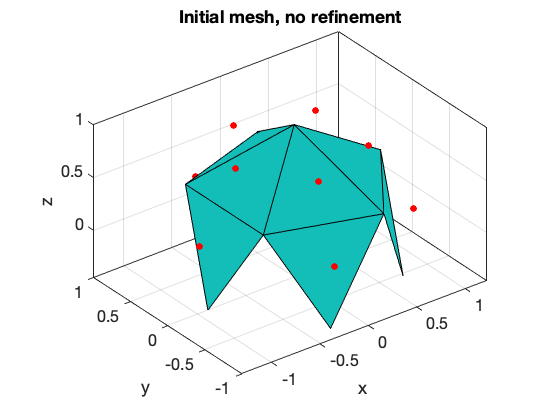

% Generate the parent mesh, with no refinement
[pnod, tricon, pcen] = spheremesh(1, 'cap');
clf
fill3elt(pnod, tricon, ones(length(pnod)))
% Add a red dot at each element centroid
hold on
plot3(pcen(1,:), pcen(2,:), pcen(3,:), 'ro', 'markerFaceColor', 'r')
title('Initial mesh, no refinement', 'FontSize', 48)

This gives ten equilateral triangles, and ten $\mathbf{p}^i$ vectors.  Matlab plots each triangular element as planar, but the red dots for the centroids are all at unit distance from the origin so they sit above the elements by a small amount.  

To increase the number of $\mathbf{p}^i$ vectors, change `nseg`, the first argument to `spheremesh`.  This will divide each edge on the initial mesh into `nseg` element edges and create $\text{nseg}^2$ new elements in each original element.  

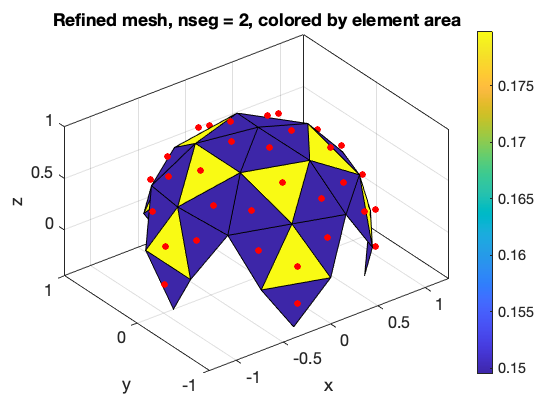

% Generate mesh nodes, connectivity, and centroids
nseg = 2;  % Controls refinement of the initial mesh
[pnod, tricon, pcen] = spheremesh(nseg, 'cap'); 
a = sphTriArea(pnod, tricon); % Element areas
% Display the mesh, colored by element area
clf
fill3elt(pnod, tricon, a);   
colorbar
% Add a red dot at each element centroid
hold on
plot3(pcen(1,:), pcen(2,:), pcen(3,:), 'ro', 'markerFaceColor', 'r')
title(sprintf('Refined mesh, nseg = %i, colored by element area', nseg))

While each element of the initial shape has the same area, differences in element areas arise as the mesh is refined.  

## Example 1: Moderate Triaxial Orientation

Let's use the centroid vectors `pcen` and element areas `a` from the previous section to compute weights $f_i$ for a moderate level of orientation. 

fprintf('=== Moderate Triaxial Orientation ===\n')

=== Moderate Triaxial Orientation ===


fprintf('Input orientation tensor:\n')

Input orientation tensor:


A = diag([0.5, 0.3, 0.2])

A =     0.5000         0         0
         0    0.3000         0
         0         0    0.2000


fprintf('Corresponding F tensor')

Corresponding F tensor

F = A2F(A, 1e-9)  % Use a fairly tight tolerance on F

F =     1.5010         0         0
         0    0.9558         0
         0         0    0.6971


fprintf('Piola tensor (B-inverse):\n')

Piola tensor (B-inverse):


Binv = inv(F*F')

Binv =     0.4438         0         0
         0    1.0947         0
         0         0    2.0581


% Find psi at each point pcen
[~, npts] = size(pcen);
psi = zeros(npts, 1);
for i = 1:npts
    psi(i) = 1/ ...
    (4*pi * (pcen(:,i)' * Binv * pcen(:,i))^(3/2));
end
% Initial weights for each point
fhat = 2 * a .* psi;
% Check the normalization of the initial weights
fprintf('For nseg = %i, npts = %i:\n', nseg, npts)

For nseg = 2, npts = 40:


fprintf('   initial sum(fhat) = %f\n', sum(fhat))

   initial sum(fhat) = 0.992569


% Normalize the weights
fhat = fhat / sum(fhat);
fprintf('Orientation tensor using initial weights fhat_i:\n')

Orientation tensor using initial weights fhat_i:


Ahat = p2A(pcen, fhat)

Ahat =     0.4960    0.0000    0.0002
    0.0000    0.3001    0.0000
    0.0002    0.0000    0.2038


We can fine-tune the weights to exactly match the input orientation tensor using the function `matchA`.  

f = matchA(fhat, pcen, A);
fprintf('Orientation tensor using matched weights f_i:\n')

Orientation tensor using matched weights f_i:


Amatched = p2A(pcen, f)

Amatched =     0.5000    0.0000         0
    0.0000    0.3000    0.0000
         0    0.0000    0.2000


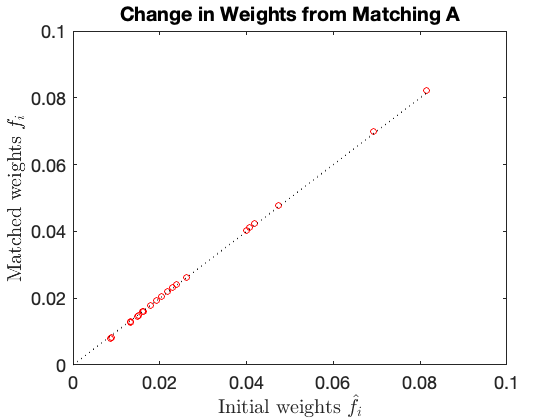

% Plot the new vs. old weights, to get an idea of how much each value
% changed.
figure
plot(fhat, f, 'ro', [0, max(f)], [0, max(f)], 'k:')
xlabel('Initial weights $\hat{f}_i$', 'Interpreter', 'LaTeX')
ylabel('Matched weights $f_i$', 'Interpreter', 'LaTeX')
title('Change in Weights from Matching A')
set(gca, 'FontSize', 18)

`The matchA function can also adjust the weights to match a fourth-order orientation tensor, though usually that would have to come from a closure approximation.`

## Example 2: Typical Shell-Layer Orientation

A typical shell-layer orientation state (similar to Eqn. (5.72)) provides a more challenging test.


fprintf('=== Typical Shell Layer Orientation ===\n')

=== Typical Shell Layer Orientation ===


fprintf('Orientation tensor from Eqn. (5.72):\n')

Orientation tensor from Eqn. (5.72):


A = [0.83, 0, 0.07; 0, 0.12, 0; 0.07, 0, 0.05]

A =     0.8300         0    0.0700
         0    0.1200         0
    0.0700         0    0.0500


fprintf('Corresponding F tensor:')

Corresponding F tensor:

F = A2F(A, 1e-9)  % Use a fairly tight tolerance on F

F =     4.2961         0    0.3523
         0    0.6819         0
    0.3523         0    0.3703


fprintf('Piola tensor (B-inverse):\n')

Piola tensor (B-inverse):


Binv = inv(F*F')

Binv =     0.1215         0   -0.7644
         0    2.1507         0
   -0.7644         0    8.6395


% Find psi at each point pcen
[~, npts] = size(pcen);
psi = zeros(npts, 1);
for i = 1:npts
    psi(i) = 1/ ...
    (4*pi * (pcen(:,i)' * Binv * pcen(:,i))^(3/2));
end
% Initial weights for each point
fhat = 2 * a .* psi;
% Check the normalization of the initial weights
fprintf('For nseg = %i, npts = %i:\n', nseg, npts)

For nseg = 2, npts = 40:


fprintf('   initial sum(fhat) = %f\n', sum(fhat))

   initial sum(fhat) = 0.925945


% Normalize the weights
fhat = fhat / sum(fhat);
fprintf('Orientation tensor using initial weights fhat_i:\n')

Orientation tensor using initial weights fhat_i:


Ahat = p2A(pcen, fhat)

Ahat =     0.8219   -0.0000    0.1232
   -0.0000    0.1113   -0.0000
    0.1232   -0.0000    0.0668


% Adjust weights to match A exactly
f = matchA(fhat, pcen, A);

fprintf('Orientation tensor using matched weights f_i:\n')

Orientation tensor using matched weights f_i:


Amatched = p2A(pcen, f)

Amatched =     0.8300   -0.0000    0.0700
   -0.0000    0.1200   -0.0000
    0.0700   -0.0000    0.0500


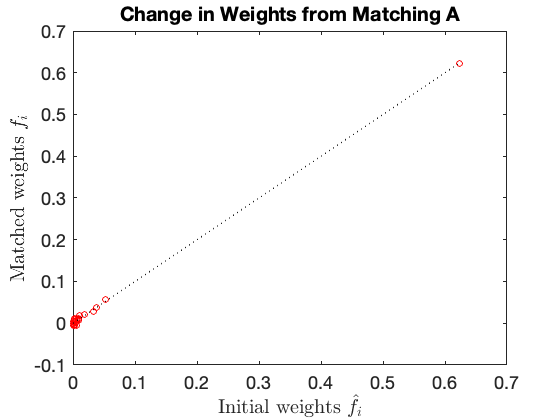

% Plot the new vs. old weights, to get an idea of how much each value
% changed.
figure
plot(fhat, f, 'ro', [0, max(f)], [0, max(f)], 'k:')
xlabel('Initial weights $\hat{f}_i$', 'Interpreter', 'LaTeX')
ylabel('Matched weights $f_i$', 'Interpreter', 'LaTeX')
title('Change in Weights from Matching A')
set(gca, 'FontSize', 18)

In this example, adjusting the weights to match the second-order tensor results in a substantial number of negative $f_i$ values.  (Note the warning message in the window on the right.)  The negative values were all small to begin with, but the new values are still less than zero.  Click in the figure and use the zoom and pan tools to see the details near $f_i = 0$.  

Simply increasing the number of points (increasing `nseg` on line 10 and re-running the entire script) does not eliminate the problem.  This is a weakness of the constrained least-squares approach used by `matchA` to adjust the weighting factors.  

The practical option at the moment is to not use `matchA` in these cases, and accept some inaccuracy in matching the second-order tensor.  `matchA` can return the number of negative weights, so the decision to use the inital or the matched weights can be automated.  